xiaoyuImageSegTest

Shuai Yang

2021/12/20

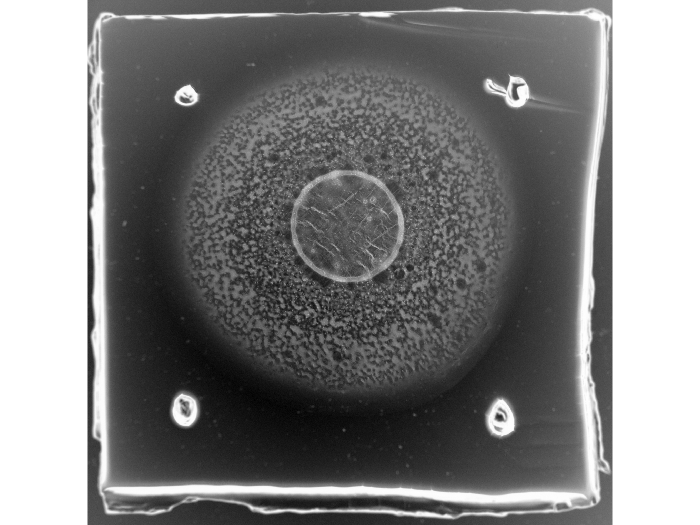

dirIm = 'C:\Users\XJY\Desktop\test\6.tif';
I0 = imread(dirIm);

I0 = rescale(double(I0))*255;
I0 = 255-I0;
I0 = uint8(I0);
imshow(I0);

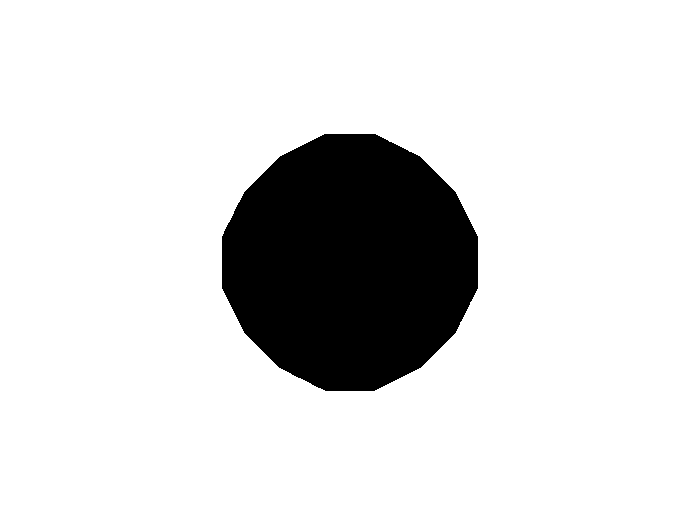




edgeFilter=(ones(5,5)).*-1;edgeFilter(3,3)=24;%created edgefilter
I1 = imgaussfilt(I0, 2);

I2 = imfilter(I1,edgeFilter);
% imshow(I2)

sz = size(I0);
I_border = ones(sz)*255; I_border(150:sz(1)-150,150:sz(2)-150) = 0;
I_border =uint8(I_border);
I2 = imsubtract(I2,I_border);
% imshow(I2)
I3 = imgaussfilt(I2,2);
% imshow(I3)
level = graythresh(I3);

I4 = imbinarize(I3, level/1.1);

center_L = 500;
I_Center = false(sz);
I_Center(round(sz(1)/2),(round(sz(2)/2))) = true;
I_Center = imdilate(I_Center,strel('disk',center_L,8));
I_Center = 1-I_Center;
imshow(I_Center)

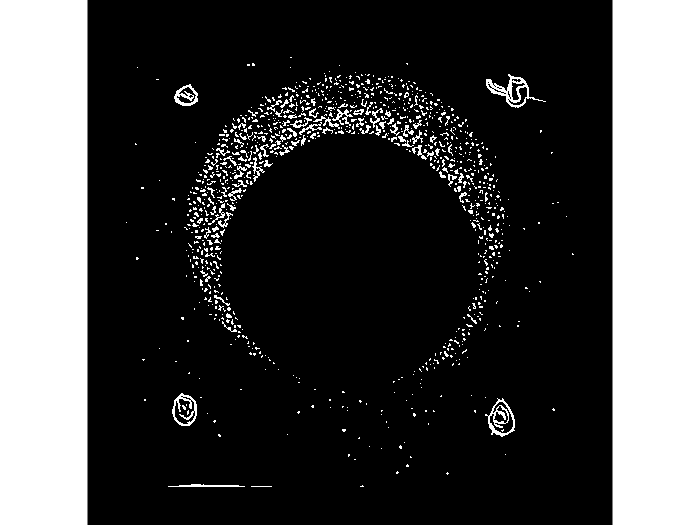

% I4(sz(1)/2-center_L:sz(1)/2+center_L,sz(2)/2-center_L:sz(2)/2+center_L) = uint8(0);
% imshow(I4)
I4 = I4&I_Center;
imshow(I4)

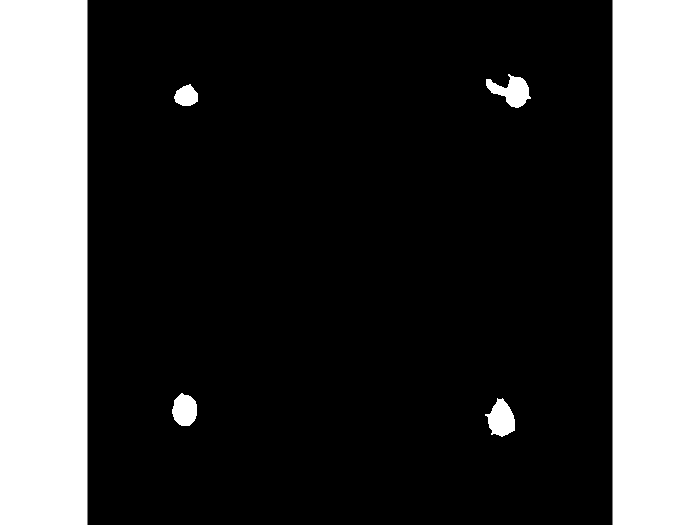

I5 = bwareaopen(I4,1500);
% figure,imshowpair(I0,I4,'montage')

% imshow(I5)


se = strel('disk',10);
I6 = imclose(I5,se);
% imshow(I6)
I7 = imfill(I6,'holes');
% imshow(I7)


r = regionprops(I7,'Area','Centroid','Circularity');

f = find(([r.Circularity] < 0.4));

L = bwlabel(I7);
goodones = setdiff(1:max(max(L)), f);
I8 = ismember(L, goodones);
imshow(I8)

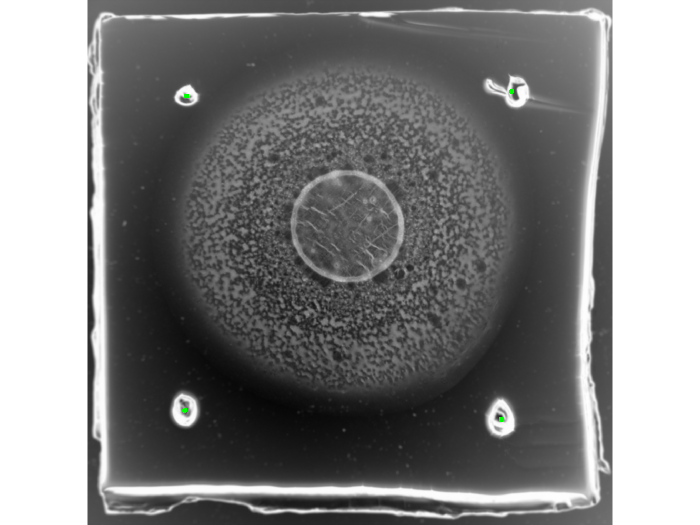


s =  regionprops(I8,'Centroid');
cali_Pts = zeros(numel(s),2);
I9 = false(sz);
for i= 1:numel(s)
    I9(round(s(i).Centroid(2)),round(s(i).Centroid(1))) = true; 
    cali_Pts(i,:) = s(i).Centroid;
end

I9 = imdilate(I9,se);
I10 = imoverlay(I1,I9,[0,1,0]);
imshow(I10)